# lora sim

symbol time caclulator

## lora parameters

%clear
SF=12;
numSym=3;
BW=125e3;%samples per sec
Fs=BW;
SPS=(2^SF);%samples per lora symbol



## simulation parameters

dataLength=SF*numSym;
randomData=true;
nLoops=1;
filtersOn=false;
plotSpec=false;
maxSNR=22;
dopplerShift=00e3;


## transmitter

%generate data
if randomData
    messageBits= randi([0 1],dataLength,1)
else
    messageBits=ones(dataLength,1)
end

messageBits =      0
     1
     1
     1
     1
     0
     0
     0
     0
     1


messageSymbols=reshape(messageBits,[],SF)%group in symbols, SF bits per symbol

messageSymbols =      0     1     0     1     1     0     0     0     0     1     1     1
     1     1     0     1     0     0     1     1     0     1     0     0
     1     0     0     0     0     1     1     1     0     1     1     1


decimalSymbols=binaryVectorToDecimal(messageSymbols)%to check the value

decimalSymbols =         1415
        3380
        2167


loraSymbols=zeros(SPS,numSym);%%every colum contains the samples of one symbol
for m=1:numSym
    k=binaryVectorToDecimal(messageSymbols(m,:));
    for n=1:SPS
        if k >= SPS %wrap around by 2^SF
            k=k-SPS;
        end 
        k = k+1;
        loraSymbols(n,m)=(1/(sqrt(2^SF)))*exp(1i*2*pi*k*(k/(2^SF*2)));
    end
end

txSignal=reshape(loraSymbols,[],1);

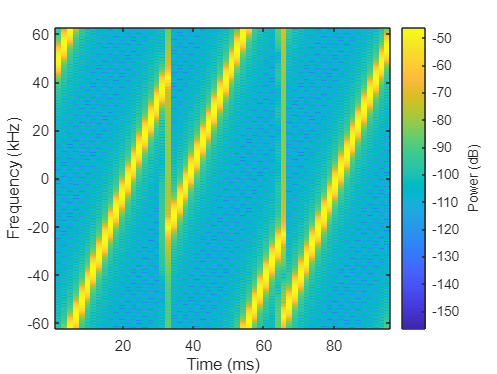

%plot
spectrogram(txSignal(1:3*(2^SF)),round((2^SF)/10),round(((2^SF)/10)/2),2^SF,Fs,'power','centered', 'yaxis');

## channel

symbolDuration=(2^SF)/Fs;

t=(symbolDuration/2^SF:symbolDuration/2^SF:symbolDuration*numSym);

dopplerEffect = exp(1i * 2 * pi * dopplerShift * t);
txSignalDopplerShifted = txSignal .* dopplerEffect';




## receiver

%generate base downchirp
    base_down_chirp=zeros(1,SPS);
    k=0;
    for n=1:SPS
        if k>= (2^SF)
            k=k-2^SF;
        end
        k=k+1;
        base_down_chirp(n)=(1/(sqrt(2^SF)))*exp(-1i*2*pi*k*(k/(2^SF*2)));
    end

for i=1:numSym
    dechirped=transpose(txSignal(((i-1)*SPS)+1:i*SPS)).*base_down_chirp;

    corrs=(abs(fft(dechirped)).^2);
    [~, ind]=max(corrs);
    dechirpedSymbols(i)=ind-1; %-1 wantDC wordt meegecount in fft dus alles is +1
   
end
dechirpedSymbols

dechirpedSymbols =         1415        3380        2167


decodedBits=reshape(decimalToBinaryVector(dechirpedSymbols,SF),[],1);

errors=sum(decodedBits~=messageBits)

errors = 0